ECE-524 Spring 2025

Author: Cristian Salitre

01-15-2025

% ECE 524 - Radio System Design HW1
% 
clc;
clear;

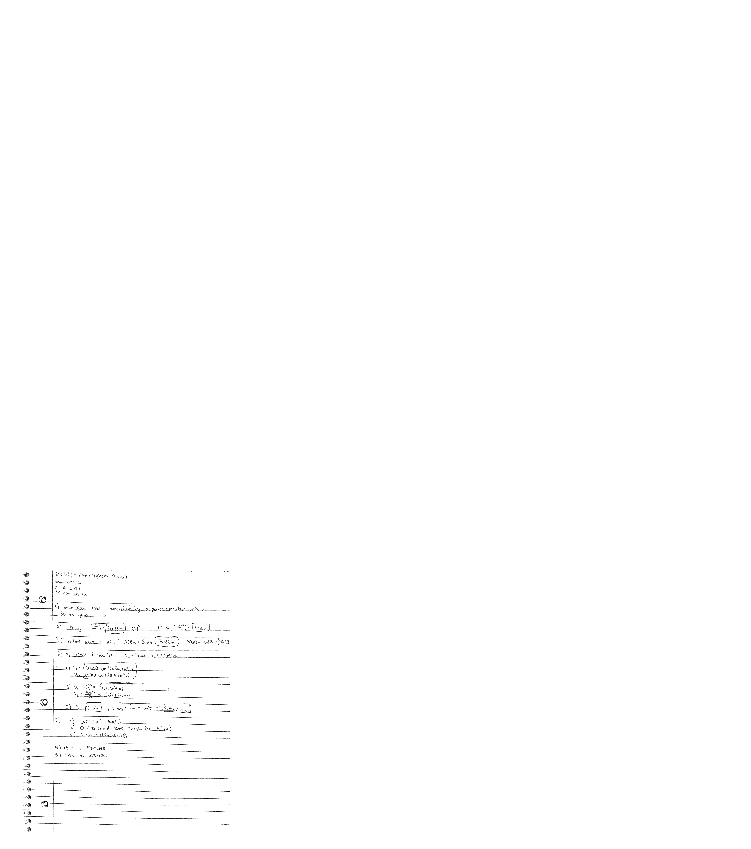

% Open handwritten part of HW1
HW1_img = imread('HW1_written.png');
figure('Units', 'normalized', 'OuterPosition', [0 0 1 1]);
imshow(HW1_img, 'InitialMagnification', 100);

**Problem 4: For each signal from problem 2, plot in Matlab of how the signals look in the time domain**

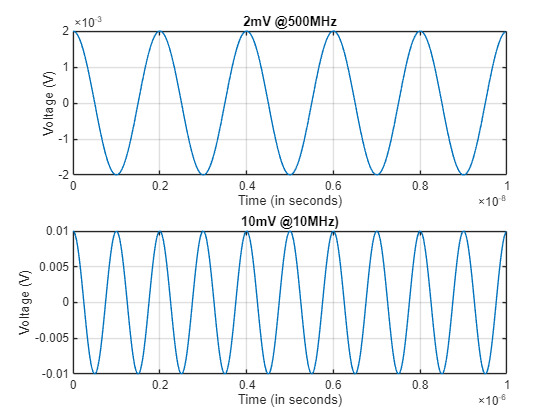

% Problem 4: Plot the following signals in the time domain
% v1: 0.002 cos(2pi(500x10^6)t)
% v2: 0.01 cos(2pi(10x10^6)t)

% Freuencies of signals
F1 = 500e6; % 500 MHz
F2 = 10e6; % 10 MHz

% Signal V1
Fs1 = F1 * 50;  % Sampling at 50x frequency
Ts1 = 1 / Fs1; 
t1 = (0:Ts1:1e-8-Ts1);
x1 = 2e-3*cos(2*pi*F1*t1);

% Signal V2
Fs2 = F2 * 50;
Ts2 = 1 / Fs2;
t2 = (0:Ts2:1e-6-Ts2);
x2 = 10e-3*cos(2*pi*F2*t2); % different time base

% Plot V1
figure;
subplot(2,1,1);
plot(t1,x1);
title('2mV @500MHz')
xlabel('Time (in seconds)');
ylabel('Voltage (V)');
grid on;


% Plot V2
subplot(2,1,2);
plot(t2,x2);
title('10mV @10MHz)')
xlabel('Time (in seconds)');
ylabel('Voltage (V)');
grid on;

**Problem 5: For the added signals from problem 3, plot in Matlab of how the signal look in the time domain.**

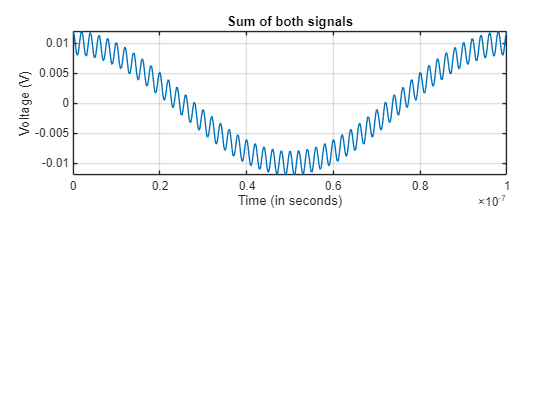

% Problem 5
%
% Added Signal: V1 + V2 
% 0.002 cos(2pi(500x10^6)t) + 0.01 cos(2pi(10x10^6)t)

Fs = max(F1, F2) * 50;
Ts = 1 / Fs;
t = 0:Ts:1e-7 - Ts;
x11 = 2e-3*cos(2*pi*F1*t);
x22 = 10e-3*cos(2*pi*F2*t); 
x_sum = x11 + x22;

% Plot different time base
figure;
subplot(2,1,1);
plot(t, x_sum);
title('Sum of both signals');
xlabel('Time (in seconds)');
ylabel('Voltage (V)');
grid on;